%% End-to-End Sentinel-2 Pixel Classification Pipeline (1D-CNN)
% Pixel-wise coastal habitat classification into Seagrass, Sand, Water, and Clouds
clear; clc; close all;

%% ========================================================================
% STEP 1: INITIALIZATION & PATHS
%   - Configure data folder
%   - Define file patterns, band labels, and class names
% =========================================================================

% Allow external configuration of dataFolder (e.g. from a simple UI)
if ~exist('dataFolder','var') || isempty(dataFolder)
    % Default folder path (used if not provided by caller)
    dataFolder = "C:\Users\James\OneDrive\Documents\James\BSU\OTHERs\Industry Innovation Challenge\Coastal_Area_NRG";
end

csvFile    = fullfile(dataFolder, 'Ground_Truth.csv');
tciPattern = fullfile(dataFolder, '*True_color.tiff'); 

% 12 Sentinel-2 bands for classification 
bandLabels = ["B01","B02","B03","B04","B05","B06","B07","B08","B8A","B09","B11","B12"];
numBands = length(bandLabels);

% Your 4 specific QGIS classes
classNames = ["Seagrass", "Sand", "Water", "Clouds"];
numClasses = length(classNames);  % 4

disp('Step 1 Complete: Workspace initialized.');

Step 1 Complete: Workspace initialized.



%% ========================================================================
% STEP 2: LOAD SATELLITE BANDS, BUILD FEATURE STACK & MASKS
% =========================================================================

% Be flexible with band file naming: accept any .tif/.tiff that contains
% the band code (e.g. B02) in the filename, regardless of extra text.
allTiffFiles = dir(fullfile(dataFolder, "*.tif*"));
bandData = cell(numBands, 1);

disp("--- Loading Spectral Bands ---");

--- Loading Spectral Bands ---



for b = 1:numBands
    searchPattern = upper(string(bandLabels(b))); % e.g. "B02"
    for i = 1:length(allTiffFiles)
        nameUpper = upper(allTiffFiles(i).name);
        if contains(nameUpper, searchPattern)
            img = imread(fullfile(dataFolder, allTiffFiles(i).name));
            if ndims(img) > 2
                img = img(:,:,1);
            end
            bandData{b} = double(img);
            break;
        end
    end
    if isempty(bandData{b})
        error("Band %s not found in folder %s.", bandLabels(b), dataFolder);
    end
end

% -------------------------------------------------------------------------
% Build 3D Band Matrix  [Rows x Cols x 12]
% -------------------------------------------------------------------------
baseSize = size(bandData{1});
bandMatrix = zeros([baseSize, numBands], 'double');

for k = 1:numBands
    bandMatrix(:,:,k) = bandData{k};
end

[rows, cols, ~] = size(bandMatrix);

disp("Raw 12-band stack created successfully.");

Raw 12-band stack created successfully.



% ------------------------------------------------------------------------
% COMPUTE SPECTRAL INDICES
% -------------------------------------------------------------------------

% Extract required bands
B02 = bandMatrix(:,:,2);   % Blue
B03 = bandMatrix(:,:,3);   % Green
B04 = bandMatrix(:,:,4);   % Red
B08 = bandMatrix(:,:,8);   % NIR
B11 = bandMatrix(:,:,11);  % SWIR

% --- NDVI (Vegetation) ---
NDVI = (B08 - B04) ./ (B08 + B04 + eps);

% --- NDWI (Water detection using NIR) ---
NDWI = (B03 - B08) ./ (B03 + B08 + eps);

% --- MNDWI (Improved water detection using SWIR) ---
MNDWI = (B03 - B11) ./ (B03 + B11 + eps);

% --- BRIGHTNESS INDEX ---
Brightness = (B02 + B03 + B04)/3;  % Average of visible bands

% -------------------------------------------------------------------------
% Append indices to bandMatrix
% -------------------------------------------------------------------------
bandMatrix(:,:,13) = NDVI;
bandMatrix(:,:,14) = NDWI;
bandMatrix(:,:,15) = MNDWI;
bandMatrix(:,:,16) = Brightness;

numBands = 16;

fprintf("Final feature stack size: %dx%dx%d\n", rows, cols, numBands);

Final feature stack size: 460x475x16



% ------------------------------------------------------------------------
% CREATE MASKS
% -------------------------------------------------------------------------

% --- WATER MASK (NDWI/MNDWI-based; better coastal separation) ---
waterMask = (NDWI > 0.02) | (MNDWI > 0.02);

% --- LAND MASK ---
landMask = ~waterMask;

disp("Masks created successfully.");

Masks created successfully.



% ------------------------------------------------------------------------
% Load True Color Image and Spatial Reference
% -------------------------------------------------------------------------

tciList = dir(tciPattern);

if isempty(tciList)
    error('True Color image (*True_color.tiff) not found.');
end

tciFile = fullfile(dataFolder, tciList(1).name);

tciImage = imread(char(tciFile));
[~, R] = readgeoraster(char(tciFile));

disp("Step 2 Complete: Feature stack and masks ready.");

Step 2 Complete: Feature stack and masks ready.



%% ========================================================================
% STEP 3: CSV PARSER & LABEL MAP
% =========================================================================
disp("Parsing ground truth CSV...");

Parsing ground truth CSV...


T = readtable(csvFile);

% Extract arrays directly to prevent concatenation errors
lat_array = T.Latitude;
lon_array = T.Longitude;
class_array = T.Value;

labelImage = zeros(rows, cols, 'uint8');
numLabeled = 0;

for i = 1:length(lat_array)
    lat = lat_array(i);
    lon = lon_array(i);
    label = class_array(i);
    
    if isnan(lat) || isnan(lon), continue; end
    
    % Get the raw Intrinsic (Pixel) Coordinates: X=Column, Y=Row
    if strcmp(R.CoordinateSystemType, 'geographic')
        [x_col, y_row] = geographicToIntrinsic(R, lat, lon);
    else
        [x_col, y_row] = worldToIntrinsic(R, lon, lat);
    end
    
    % Assign them strictly to the nearest pixel with boundary checks
    col = round(x_col);
    row = round(y_row);
    
    % Strict boundary check to prevent out-of-bounds errors
    if row >= 1 && row <= rows && col >= 1 && col <= cols
        labelImage(row, col) = uint8(label);
        numLabeled = numLabeled + 1;
    end
end

fprintf('---> SUCCESS: Mapped %d ground truth points to the image grid.\n', numLabeled);

---> SUCCESS: Mapped 154 ground truth points to the image grid.


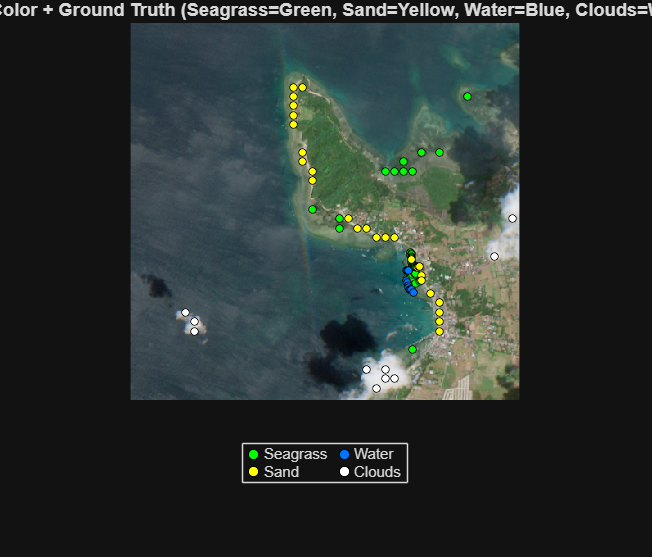


% ------------------------------------------------------------------------
% Ground Truth Visualization on True Color Image
% ------------------------------------------------------------------------
[gtRows, gtCols] = find(labelImage > 0);
gtVals = double(labelImage(labelImage > 0));

gtClassColors = [
    0.00 1.00 0.00;   % Seagrass   (Green)
    1.00 1.00 0.00;   % Sand       (Yellow)
    0.00 0.45 1.00;   % Water      (Blue)
    1.00 1.00 1.00    % Clouds     (White)
];

figure('Name','True Color with Ground Truth Points');
imshow(tciImage); hold on;

legendHandles = gobjects(numClasses,1);
for c = 1:numClasses
    classMask = (gtVals == c);
    if any(classMask)
        legendHandles(c) = scatter(gtCols(classMask), gtRows(classMask), 20, ...
            'o', 'filled', ...
            'MarkerFaceColor', gtClassColors(c,:), ...
            'MarkerEdgeColor', 'k', ...
            'DisplayName', char(classNames(c)));
    end
end

validLegend = isgraphics(legendHandles);
if any(validLegend)
    legend(legendHandles(validLegend), 'Location', 'southoutside', 'NumColumns', 2);
end

title('True Color + Ground Truth (Seagrass=Green, Sand=Yellow, Water=Blue, Clouds=White)');
hold off;


%% ========================================================================
% STEP 4: PREPARE & BALANCE DATA FOR 1D-CNN (MANUAL SPLIT)
%   - Flatten labeled pixels
%   - Manual train/val/test split
%   - Class balancing and standardization
% =========================================================================
disp("Preparing and balancing data for 1D-CNN...");

Preparing and balancing data for 1D-CNN...


featuresAll = reshape(bandMatrix, rows*cols, numBands);
labelsAll   = reshape(labelImage, rows*cols, 1);

% Keep only valid, labeled pixels (1..numClasses)
keepMask = ismember(labelsAll, 1:numClasses) & all(~isnan(featuresAll), 2);
X = featuresAll(keepMask, :);
Y = labelsAll(keepMask); 

% Create categorical labels for the neural network training later
Ycat = categorical(Y, 1:numClasses, classNames);

% -------------------------------------------------------------------------
% Manual data splitting (since we don't have a simple table to use cvpartition on)
% -------------------------------------------------------------------------
rng(0); % Keep this so your randomized split is the same every time
totalSamples = size(X, 1);
shuffledIdx = randperm(totalSamples);

% Calculate split sizes (25% Test, 10% Validation, 65% Train)
numTest = round(0.25 * totalSamples);
numVal  = round(0.10 * (totalSamples - numTest));

% Assign the indices
idxTest  = shuffledIdx(1 : numTest);
idxVal   = shuffledIdx(numTest + 1 : numTest + numVal);
idxTrain = shuffledIdx(numTest + numVal + 1 : end);

% Apply the splits
X_test  = X(idxTest, :);   Y_test  = Ycat(idxTest);
X_val   = X(idxVal, :);    Y_val   = Ycat(idxVal);
X_train = X(idxTrain, :);  Y_train = Ycat(idxTrain);
% -------------------------------------------------------------------------

% Balance Training Data (Oversampling minority classes)
tbl = countcats(Y_train);
targetCount = max(tbl);
X_train_bal = X_train; 
Y_train_bal = Y_train;
cats = categories(Y_train);

for c = 1:numel(cats)
    curMask = (Y_train == cats{c});
    curN = sum(curMask);
    if curN < targetCount && curN > 0
        idx = find(curMask);
        repIdx = idx(randi(numel(idx), targetCount - curN, 1));
        X_train_bal = [X_train_bal; X_train(repIdx, :)];
        Y_train_bal = [Y_train_bal; Y_train(repIdx)];
    end
end

% Standardize (Z-Score Normalization)
mu = mean(X_train_bal, 1);
sigma = std(X_train_bal, 0, 1) + eps;
Xtrain_z = (X_train_bal - mu) ./ sigma;
Xval_z   = (X_val - mu) ./ sigma;
Xtest_z  = (X_test - mu) ./ sigma;

% Reshape for CNN [Bands x 1 x 1 x Samples]
Xtrain4 = reshape(Xtrain_z', [numBands, 1, 1, size(Xtrain_z, 1)]);
Xval4   = reshape(Xval_z',   [numBands, 1, 1, size(Xval_z, 1)]);
Xtest4  = reshape(Xtest_z',  [numBands, 1, 1, size(Xtest_z, 1)]);

disp('Step 4 Complete: Data is split (manually!), balanced, and ready for the CNN.');

Step 4 Complete: Data is split (manually!), balanced, and ready for the CNN.



%% ========================================================================
% STEP 4.5: OPTIONAL DIAGNOSTIC VISUALIZATIONS
%   - Raw band grid
%   - Spectral index maps (NDVI, NDWI, MNDWI, Brightness)
% =========================================================================
disp("Generating diagnostic visualizations...");

Generating diagnostic visualizations...


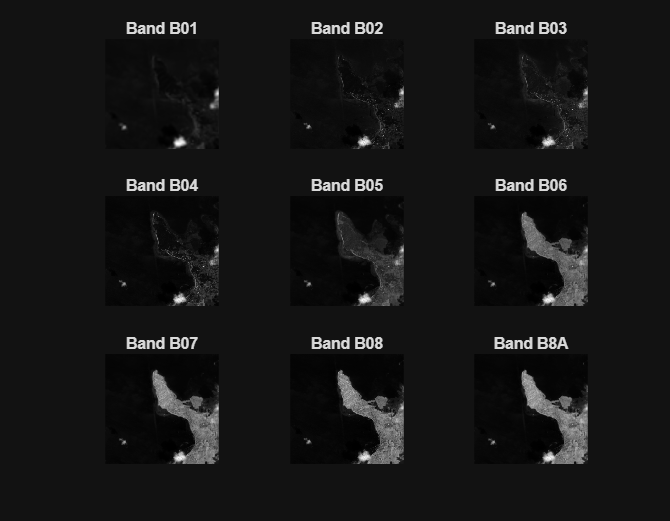


% ------------------------------------------------------------------------
% 1. Grayscale Grid of First 9 Raw Bands
% ------------------------------------------------------------------------
figure('Name', 'Grayscale Bands', 'Position', [100, 100, 900, 700]);
tiledlayout(3,3, 'TileSpacing', 'compact');

for k = 1:9
    nexttile;
    imagesc(bandMatrix(:,:,k));
    axis image off;
    colormap gray;
    title(sprintf("Band %s", bandLabels(k)));
end

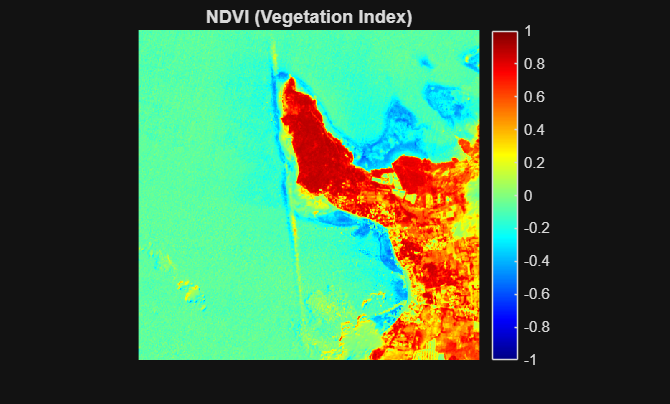


% ------------------------------------------------------------------------
% 2. False Color Composite (B08-B04-B03)
% ------------------------------------------------------------------------
showFalseColor = false;  % Optional: set true if you want this diagnostic view
if showFalseColor
    falseColor = cat(3, ...
        rescale(bandMatrix(:,:,8)), ...
        rescale(bandMatrix(:,:,4)), ...
        rescale(bandMatrix(:,:,3)));

    figure('Name', 'False Color Composite');
    imshow(falseColor);
    title("False Color Composite (NIR-Red-Green)");
end

% ------------------------------------------------------------------------
% 3. NDVI Visualization
% ------------------------------------------------------------------------
figure('Name','NDVI Map');
imagesc(NDVI);
axis image off;
colormap(jet);
colorbar;
caxis([-1 1]);
title('NDVI (Vegetation Index)');

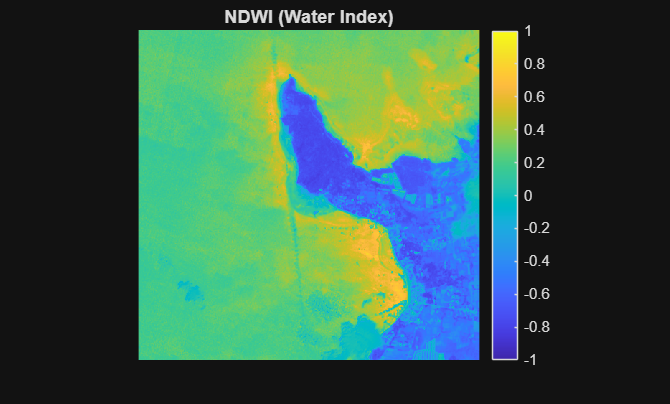


% ------------------------------------------------------------------------
% 4. NDWI Visualization
% ------------------------------------------------------------------------
figure('Name','NDWI Map');
imagesc(NDWI);
axis image off;
colormap(parula);
colorbar;
caxis([-1 1]);
title('NDWI (Water Index)');

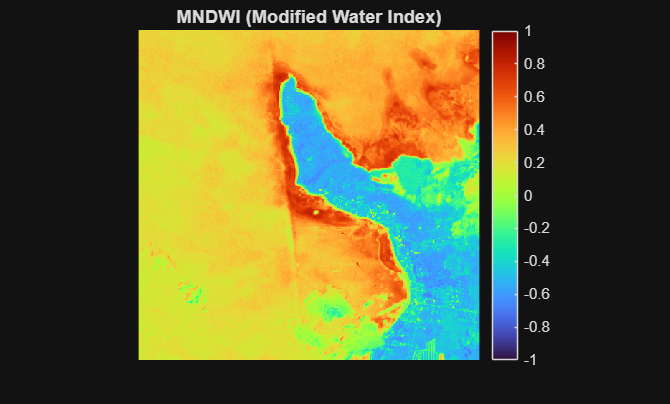


% ------------------------------------------------------------------------
% 5. MNDWI Visualization
% ------------------------------------------------------------------------
figure('Name','MNDWI Map');
imagesc(MNDWI);
axis image off;
colormap(turbo);
colorbar;
caxis([-1 1]);
title('MNDWI (Modified Water Index)');

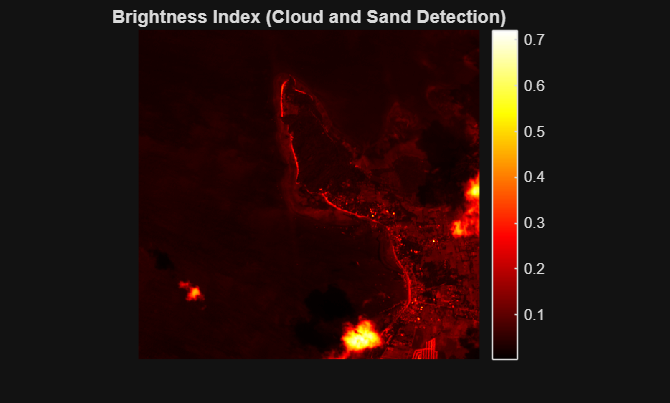


% ------------------------------------------------------------------------
% 6. Brightness Index Visualization (Better for Clouds)
% ------------------------------------------------------------------------

figure('Name','Brightness Index');
imagesc(Brightness);
axis image off;
colormap(hot);
colorbar;
title('Brightness Index (Cloud and Sand Detection)');


%% ========================================================================
% STEP 5: BUILD & TRAIN 1D-CNN
% =========================================================================
disp("Configuring Neural Network Architecture...");

Configuring Neural Network Architecture...



% Class name list used later for probability-based corrections
classCats = cellstr(classNames');

% Define the layers of the 1D Convolutional Neural Network
layers = [
    imageInputLayer([numBands 1 1], 'Normalization', 'none', 'Name', 'input')
    
    convolution2dLayer([3 1], 32, 'Padding', 'same', 'Name', 'conv1')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer([2 1], 'Stride', [2 1], 'Name', 'pool1')
    
    convolution2dLayer([3 1], 64, 'Padding', 'same', 'Name', 'conv2')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer([2 1], 'Stride', [2 1], 'Name', 'pool2')
    
    convolution2dLayer([3 1], 128, 'Padding', 'same', 'Name', 'conv3')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')
    
    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.4, 'Name', 'dropout')
    
    fullyConnectedLayer(numClasses, 'Name', 'fc_out')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')
];

miniBatchSize = 128;   % Slightly smaller batch
valFreq = max(1, floor(size(Xtrain4,4)/miniBatchSize));

options = trainingOptions('adam', ...
    'InitialLearnRate', 5e-4, ...
    'MaxEpochs',500, ...           % Train longer
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{Xval4, Y_val}, ...
    'ValidationFrequency',valFreq, ...
    'Verbose',true, ...
    'Plots','training-progress');   % Check validation each epoch

disp("Training Neural Network...");

Training Neural Network...


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       15.62% |       50.00% |       1.8581 |       1.1784 |          0.0005 |
|       2 |           2 |       00:00:06 |       45.31% |       25.00% |       1.2034 |       1.2328 |          0.0005 |
|       3 |           3 |       00:00:07 |       63.28% |       37.50% |       0.8748 |       1.2835 |          0.0005 |
|       4 |           4 |       00:00:07 |       65.62% |       37.50% |       0.7757 |       1.3163 |          0.0005 |
|       

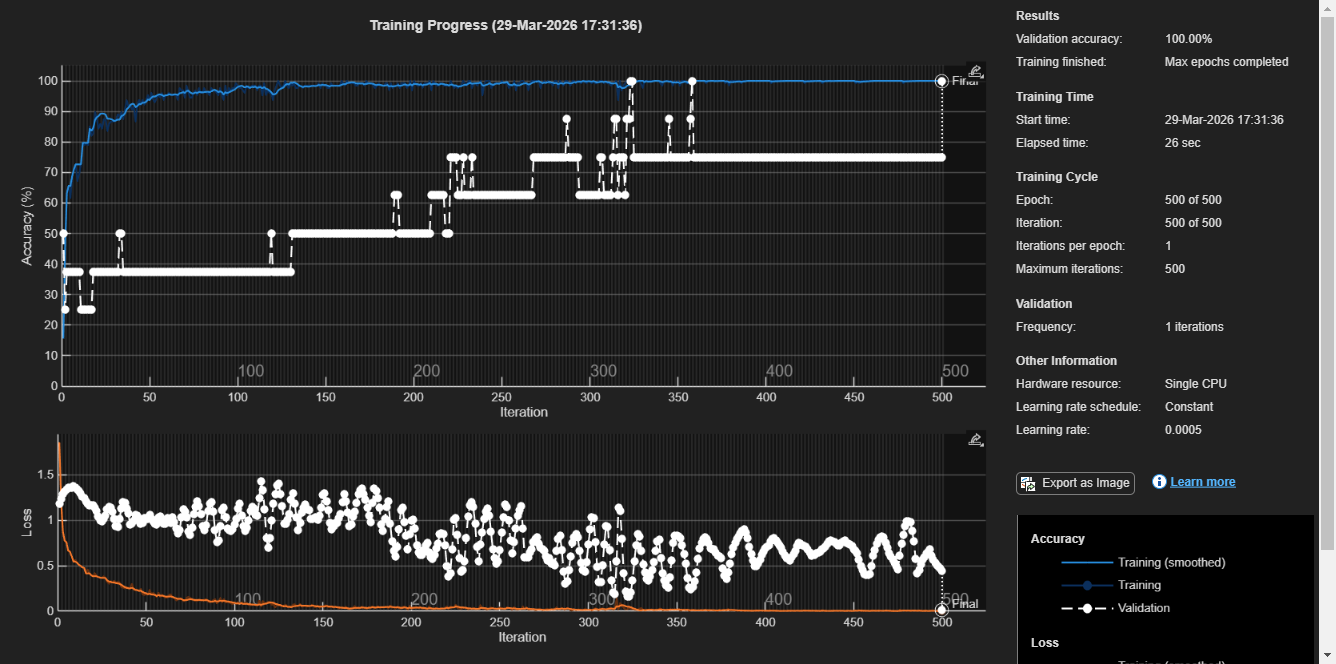

% This will open the training progress graph in your Live Editor output!
net = trainNetwork(Xtrain4, Y_train_bal, layers, options);


% Save the trained model and preprocessing parameters next to the data
modelSaveFile = fullfile(dataFolder, 'CoastalClassifier_Model.mat');
save(modelSaveFile, 'net', 'mu', 'sigma', 'classNames', 'classCats', 'numBands', 'numClasses', '-v7.3');
fprintf('Model saved to: %s\n', modelSaveFile);

Model saved to: C:\Users\James\OneDrive\Documents\James\BSU\OTHERs\Industry Innovation Challenge\Coastal_Area_NRG\CoastalClassifier_Model.mat



% Also export/update a central copy next to this script so that
% classification UIs can automatically use the latest trained model
% without asking the user to browse for a file.
scriptFolder = fileparts(mfilename('fullpath'));
modelExportFolder = fullfile(scriptFolder, 'Model_Export');
if ~exist(modelExportFolder, 'dir')
    mkdir(modelExportFolder);
end
modelExportPath = fullfile(modelExportFolder, 'coastal_area_latest_model.mat');
save(modelExportPath, 'net', 'mu', 'sigma', 'classNames', 'classCats', 'numBands', 'numClasses', '-v7.3');
fprintf('Central model copy exported to: %s\n', modelExportPath);

Central model copy exported to: C:\Users\James\AppData\Local\Temp\Editor_bfvba\Model_Export\coastal_area_latest_model.mat



% Evaluate Model on the Test Set
disp("Evaluating final model accuracy...");

Evaluating final model accuracy...


[YPred_test_raw, scores_test] = classify(net, Xtest4, 'MiniBatchSize', miniBatchSize);

rawAccuracy = mean(YPred_test_raw == Y_test) * 100;

% Probability-based correction: low-confidence Clouds with high Sand score -> Sand
cloudLabel = categorical("Clouds", classNames);
sandLabel  = categorical("Sand",   classNames);

iCloud = find(strcmp(classCats, 'Clouds'));
iSand  = find(strcmp(classCats, 'Sand'));

YPred_test = YPred_test_raw;
if ~isempty(iCloud) && ~isempty(iSand)
    isCloud  = (YPred_test == cloudLabel);
    lowConf  = scores_test(:, iCloud) < 0.5;   % stricter: cloud prob < 0.5
    sandHigh = scores_test(:, iSand)  > 0.5;   % require high sand confidence
    flipMask = isCloud & lowConf & sandHigh;
    YPred_test(flipMask) = sandLabel;
end

testAccuracy = mean(YPred_test == Y_test) * 100;

fprintf('Raw Test Accuracy: %.2f%%%%\n', rawAccuracy);

Raw Test Accuracy: 71.43%%


fprintf('Adjusted Test Accuracy (Sand/Cloud rule): %.2f%%%%\n', testAccuracy);

Adjusted Test Accuracy (Sand/Cloud rule): 71.43%%


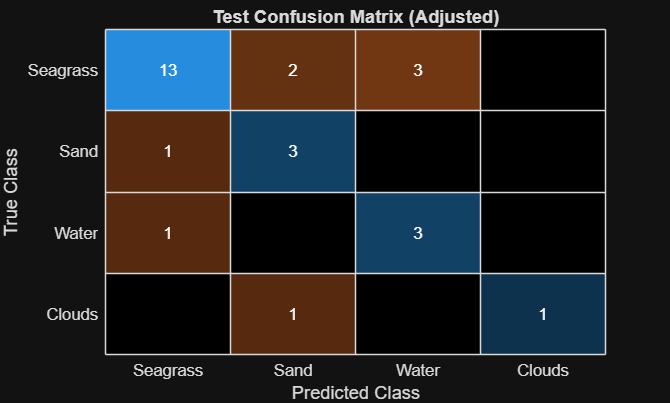


% Optional confusion matrix (if the function is available)
if exist('confusionchart','file')
    figure;
    confusionchart(Y_test, YPred_test, 'Title', 'Test Confusion Matrix (Adjusted)');
end


% Check how many pixels are predicted as clouds (after adjustment)
tabulate(double(YPred_test)); % Or use simple count with sum(YPred_test==class)

  Value    Count   Percent
      1       15     53.57%
      2        6     21.43%
      3        6     21.43%
      4        1      3.57%




%% ========================================================================
% 6. FULL IMAGE PREDICTION (ONLY COASTAL/WATER PIXELS)
% =========================================================================
disp('Classifying all coastal/water pixels across the map...');

Classifying all coastal/water pixels across the map...



% -------------------------
% Create land mask (for visualization and coastal masking)
% -------------------------
landMask = ~waterMask;   

% Flatten label image for indexing
labelsAllFlat = reshape(labelImage, rows*cols, 1);

% Unknown pixels = all locations without ground truth
unknownMaskAll = (labelsAllFlat == 0);
X_unknown = featuresAll(unknownMaskAll, :);

% Prepare new labels
newLabels = labelsAllFlat;

if ~isempty(X_unknown)
    % Standardize using training mean/std
    X_unknown_z = (X_unknown - mu) ./ sigma;
    Xunknown4 = reshape(X_unknown_z', [numBands, 1, 1, size(X_unknown_z, 1)]);
    
    % CNN prediction with sand/cloud probability-based correction
    [Ypred_unknown_raw, scores_unknown] = classify(net, Xunknown4, 'MiniBatchSize', miniBatchSize);

    Ypred_unknown = Ypred_unknown_raw;
    if ~isempty(iCloud) && ~isempty(iSand)
        isCloud_u  = (Ypred_unknown == cloudLabel);
        lowConf_u  = scores_unknown(:, iCloud) < 0.5;  % stricter cloud threshold
        sandHigh_u = scores_unknown(:, iSand)  > 0.5;  % require high sand confidence
        flipMask_u = isCloud_u & lowConf_u & sandHigh_u;
        Ypred_unknown(flipMask_u) = sandLabel;
    end

    newLabels(unknownMaskAll) = double(Ypred_unknown);
end

% Preserve original ground truth
newLabels(labelsAllFlat ~= 0) = labelsAllFlat(labelsAllFlat ~= 0);

% Reshape to image
classifiedImage = reshape(newLabels, rows, cols);

% ------------------------------------------------------------------------
% RULE-BASED CLEANUP TO REDUCE SAND OVERESTIMATION
% 1) In inland/non-water NDWI areas, Sand -> Land/Original (class 0).
% 2) In strong water areas (water mask & positive NDWI), Sand -> Water.
% 3) Enforce coastal buffer: inland Sand/Water -> Land/Original.
% ------------------------------------------------------------------------

classifiedClean = classifiedImage;
unlabeledMaskImage = reshape(labelsAllFlat == 0, rows, cols);

% Inland/non-water by NDWI (apply only to unlabeled pixels)
inlandMask = (NDWI < -0.05) & ~waterMask & unlabeledMaskImage;
classifiedClean(inlandMask & (classifiedClean == 2)) = 0; % Sand -> Land/Original

% Strong water: in water mask with NDWI > 0
waterStrongMask = waterMask & (NDWI > 0) & unlabeledMaskImage;
classifiedClean(waterStrongMask & (classifiedClean == 2)) = 3; % Sand -> Water

% Coastal buffer : pixels within ~5 px of water
kernel = ones(11,11);
coastalBufferMask = conv2(double(waterMask), kernel, 'same') > 0;

% In unlabeled inland pixels outside coastal buffer, remove Sand/Water
inlandFarMask = ~coastalBufferMask & unlabeledMaskImage;
classifiedClean(inlandFarMask & (classifiedClean == 2 | classifiedClean == 3)) = 0; % -> Land/Original

% Use cleaned classification for all subsequent analysis/visualization
classifiedImage = classifiedClean;

% Optional: Count pixels per class without toolbox
uniqueClasses = unique(classifiedImage(:));
fprintf('Class pixel counts:\n');

Class pixel counts:


for i = 1:length(uniqueClasses)
    cls = uniqueClasses(i);
    count = sum(classifiedImage(:) == cls);
    fprintf('Class %d: %d pixels\n', cls, count);
end

Class 0: 44267 pixels
Class 1: 11821 pixels
Class 2: 1638 pixels
Class 3: 157222 pixels
Class 4: 3552 pixels




%% ========================================================================
% 7. FINAL VISUALIZATION & EXPORT
% =========================================================================
% Base: original True Color image
rgbBase = im2double(tciImage);

% Prepare overlay for classified pixels
overlayR = zeros(rows, cols);
overlayG = zeros(rows, cols);
overlayB = zeros(rows, cols);

% Only apply overlay to coastal/water pixels for seagrass, sand, sea.
% Clouds are shown everywhere they are predicted.
coastalMask = ~landMask;

% Seagrass = Green
overlayG(classifiedImage == 1 & coastalMask) = 1;

% Sand = Yellow (Red + Green)
overlayR(classifiedImage == 2 & coastalMask) = 1;
overlayG(classifiedImage == 2 & coastalMask) = 1;

% Sea = Blue
overlayB(classifiedImage == 3 & coastalMask) = 1;

% Clouds = White (no coastal mask so they appear over land too)
overlayR(classifiedImage == 4) = 1;
overlayG(classifiedImage == 4) = 1;
overlayB(classifiedImage == 4) = 1;

overlay = cat(3, overlayR, overlayG, overlayB);

% Display
figure('Name','Coastal Classification with Land Intact');
imshow(rgbBase); hold on;
h = imshow(overlay);
set(h,'AlphaData',0.5);  % semi-transparent overlay

title('Sand=Yellow | Seagrass=Green | Water=Blue | Clouds=White | Land=Original');

% Save blended classified overlay image, named by date in True Color file
try
    alpha = 0.5;
    blend = rgbBase;
    mask = any(overlay > 0, 3);
    for c = 1:3
        chBase = blend(:,:,c);
        chOv   = overlay(:,:,c);
        chBase(mask) = (1-alpha) * chBase(mask) + alpha * chOv(mask);
        blend(:,:,c) = chBase;
    end

    [~, tciName, ~] = fileparts(char(tciFile));
    dateMatch = regexp(tciName, '\d{4}-\d{2}-\d{2}', 'match');
    if ~isempty(dateMatch)
        dateStr = dateMatch{1};
    else
        dateStr = 'unknown_date';
    end

    outName = sprintf('classified_overlay_%s.png', dateStr);
    outPath = fullfile(dataFolder, outName);
    imwrite(blend, outPath);
    fprintf('Saved classified overlay image to: %s\n', outPath);
catch ME
    warning('Could not save classified overlay image: %s', ME.message);
end

Saved classified overlay image to: C:\Users\James\OneDrive\Documents\James\BSU\OTHERs\Industry Innovation Challenge\Coastal_Area_NRG\classified_overlay_unknown_date.png



%% ========================================================================
% 8. SIMPLE METRICS & EXPORT FOR PRESENTATION
% =========================================================================

% Compute basic coastal pixel counts for seagrass and sand
coastalPixels = coastalMask;
totalCoastalPixels = nnz(coastalPixels);

seagrassCount = nnz(classifiedImage == 1 & coastalPixels);
sandCount     = nnz(classifiedImage == 2 & coastalPixels);

fprintf('Coastal pixel counts (within coastal mask):\n');

Coastal pixel counts (within coastal mask):


fprintf('  Total coastal pixels: %d\n', totalCoastalPixels);

  Total coastal pixels: 169701


fprintf('  Seagrass pixels: %d\n', seagrassCount);

  Seagrass pixels: 10309


fprintf('  Sand pixels    : %d\n', sandCount);

  Sand pixels    : 1208


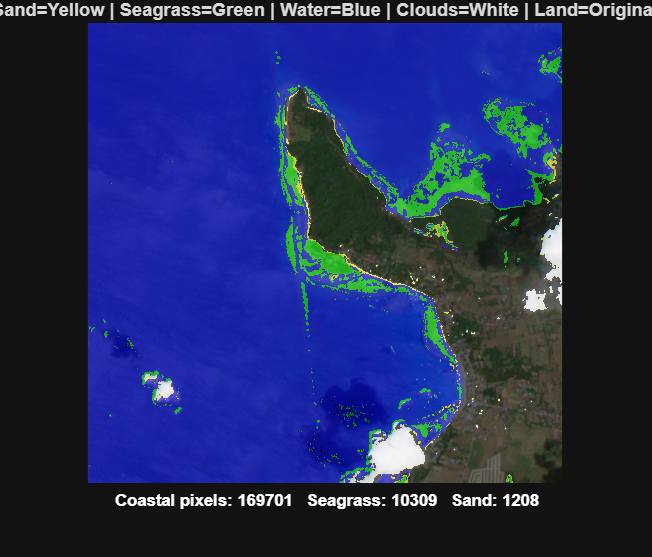


% Show counts just below the classified image figure for quick reference
try
    ax = gca;
    countsStr = sprintf('Coastal pixels: %d   Seagrass: %d   Sand: %d', ...
                        totalCoastalPixels, seagrassCount, sandCount);
    text(ax, 0.5, -0.02, countsStr, 'Units','normalized', ...
         'HorizontalAlignment','center', 'VerticalAlignment','top', ...
         'Color','w', 'FontWeight','bold');
catch
end


% Export a simple CSV with counts into the current dataFolder
try
    metricsTable = table(totalCoastalPixels, seagrassCount, sandCount, ...
        'VariableNames', {'TotalCoastalPixels','SeagrassPixels','SandPixels'});

    timestampStr = datestr(now,'yyyy-mm-dd_HHMMSS');
    metricsFile  = fullfile(dataFolder, ['coastal_metrics_' timestampStr '.csv']);
    writetable(metricsTable, metricsFile);
    fprintf('Metrics exported to: %s\n', metricsFile);
catch ME
    warning('Could not export metrics CSV: %s', ME.message);
end

Metrics exported to: C:\Users\James\OneDrive\Documents\James\BSU\OTHERs\Industry Innovation Challenge\Coastal_Area_NRG\coastal_metrics_2026-03-29_173215.csv
